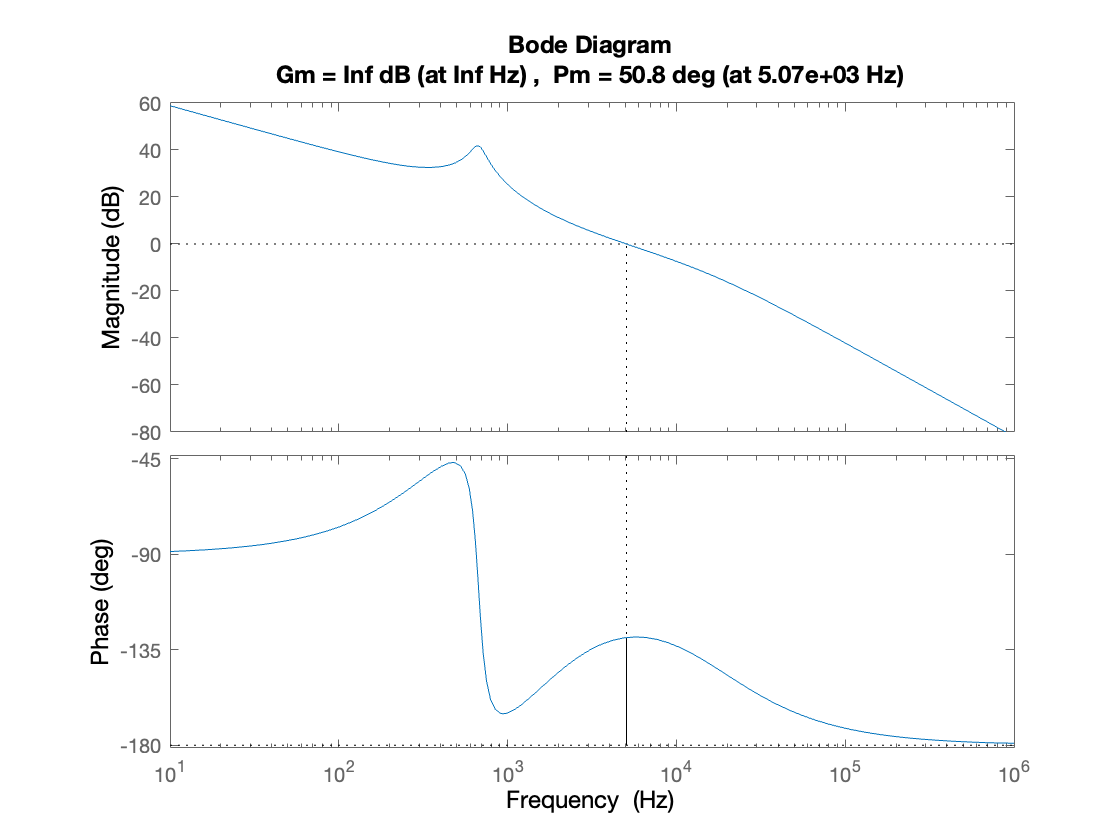

% Group 2, Lab 6
% Header/global variables:
options = bodeoptions;
options.FreqUnits = 'Hz'; 
s = tf('s');
q = 2*pi;
% Component values & Derived values
R  = 25;     Rb = 1000;    Ra = 1000;   
Vm = 10;     Vg = 10;      rL = 230e-3; 
L  = 560e-6; C  = 100e-6;  D  = 0.5;   
T0 = 0.5;    wI = q*17500; w1 = q*500;  
wz = q*1600; wp = q*16000; w0 = 673*q;
Q = (sqrt(L*C))/((rL*C)+(L/R));
% Functions:
G = 1/(s+1);
T = (T0* ((wI*(1+(s/w1))*(1+(s/wz)))))/...
    (s*(1+(s/wp))*(1+(s/(Q*w0))+((s/w0)^2)));
Gvg = D/(1+(s/(Q*w0))+((s/w0)^2));
Gvg_CL = Gvg/(1+T);
Zout = (1*rL*(1+((s*L)/rL)))/...
        (1+(s/(Q*w0))+((s/w0)^2));
Zout_CL = Zout/(1+T);
% Task 2.a.ii
margin(T)
h = gcr;
h.AxesGrid.Xunits = 'Hz'; 
h.AxesGrid.TitleStyle.FontSize=12; 
h.AxesGrid.XLabelStyle.FontSize=12;
h.AxesGrid.YLabelStyle.FontSize=12;

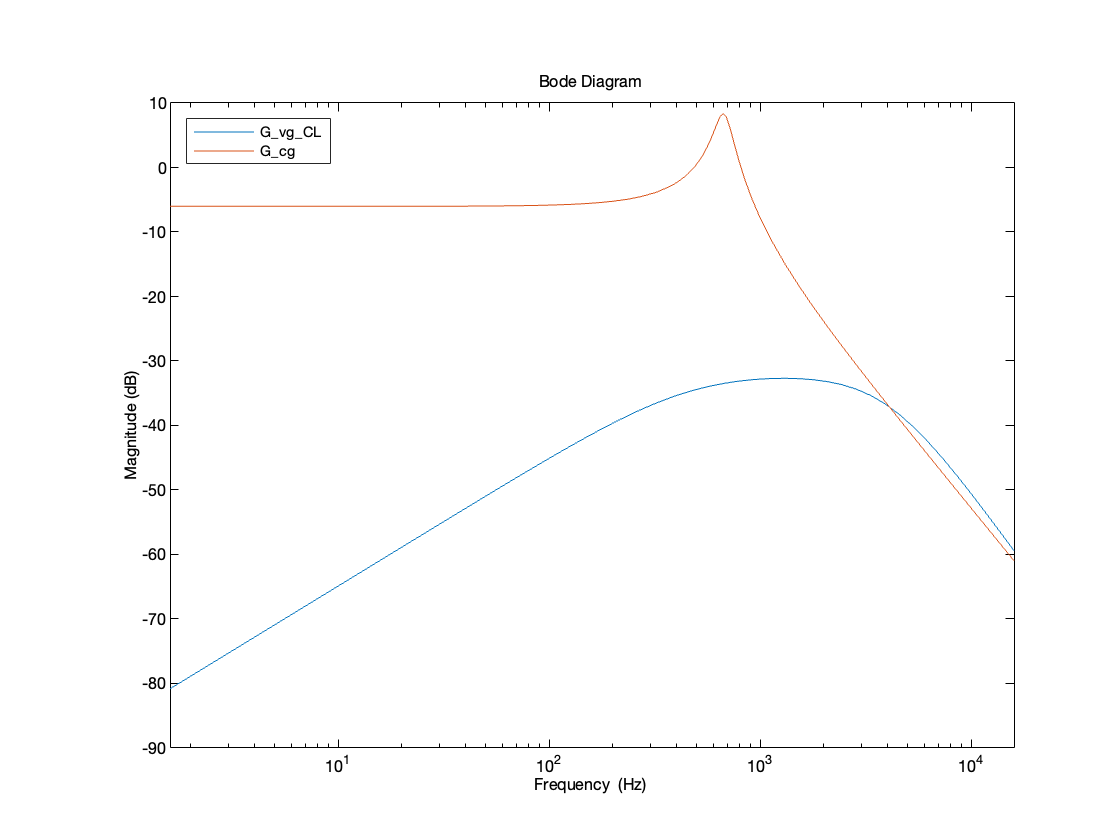

% Group 2, Lab 6
% Header/global variables:
options = bodeoptions;
options.FreqUnits = 'Hz'; 
s = tf('s');
q = 2*pi;

% Component values & Derived values
R  = 25;     Rb = 1000;    Ra = 1000;   
Vm = 10;     Vg = 10;      rL = 230e-3; 
L  = 560e-6; C  = 100e-6;  D  = 0.5;   
T0 = 0.5;    wI = q*17500; w1 = q*500;  
wz = q*1600; wp = q*16000; w0 = 673*q;
Q = (sqrt(L*C))/((rL*C)+(L/R));

% Functions:
G = 1/(s+1);
T = (D*((wI*(1+(s/w1))*(1+(s/wz)))))/...
    (s*(1+(s/wp))*(1+(s/(Q*w0))+((s/w0)^2)));
Gvg = D/(1+(s/(Q*w0))+((s/w0)^2));
Gvg_CL = Gvg/(1+T);
Zout = (1*rL*(1+((s*L)/rL)))/...
        (1+(s/(Q*w0))+((s/w0)^2));
Zout_CL = Zout/(1+T);

% Task 2.b.ii
bodemag(Gvg_CL,Gvg,options,{10e0, 10e4});
legend('G_{vg}_{CL}','G_{cg}','Location','northwest')

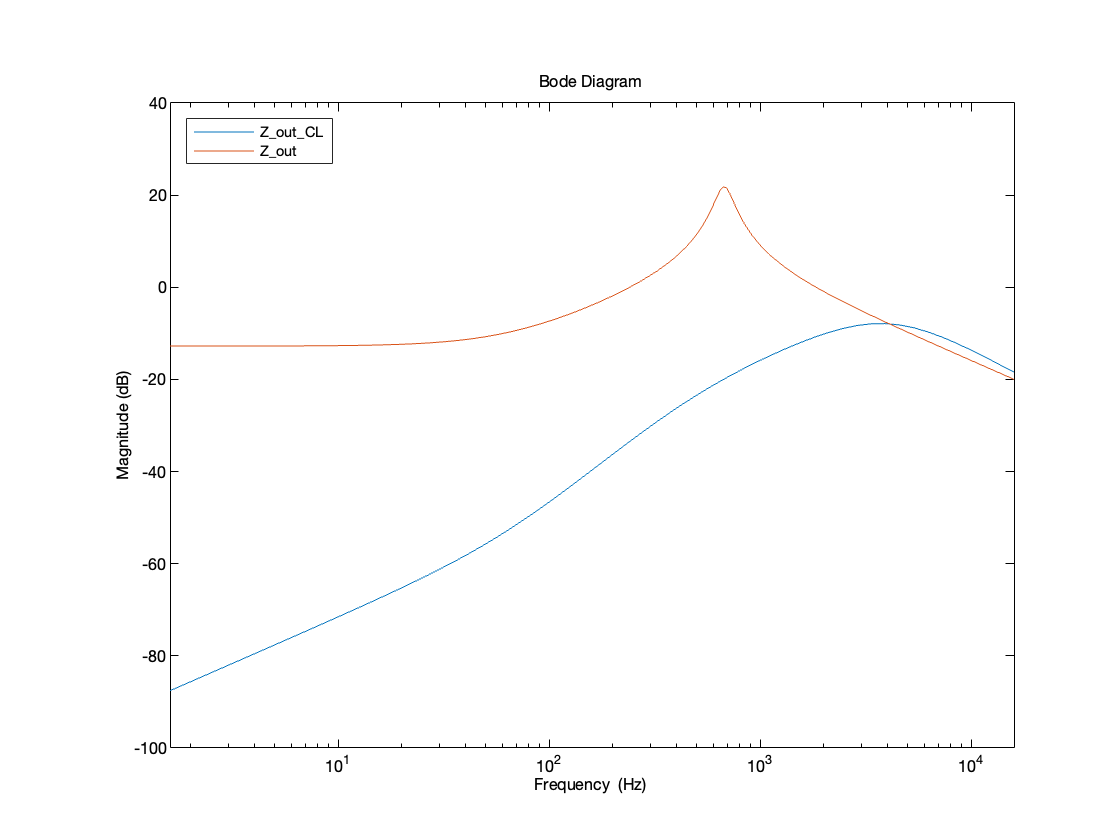

% Group 2, Lab 6
% Header/global variables:
options = bodeoptions;
options.FreqUnits = 'Hz'; 
s = tf('s');
q = 2*pi;

% Component values & Derived values
R  = 25;     Rb = 1000;    Ra = 1000;   
Vm = 10;     Vg = 10;      rL = 230e-3; 
L  = 560e-6; C  = 100e-6;  D  = 0.5;   
T0 = 0.5;    wI = q*17500; w1 = q*500;  
wz = q*1600; wp = q*16000; w0 = 673*q;
Q = (sqrt(L*C))/((rL*C)+(L/R));

% Functions:
G = 1/(s+1);
T = (D*((wI*(1+(s/w1))*(1+(s/wz)))))/...
    (s*(1+(s/wp))*(1+(s/(Q*w0))+((s/w0)^2)));
Gvg = D/(1+(s/(Q*w0))+((s/w0)^2));
Gvg_CL = Gvg/(1+T);
Zout = (1*rL*(1+((s*L)/rL)))/...
        (1+(s/(Q*w0))+((s/w0)^2));
Zout_CL = Zout/(1+T);

% Task 2.c.ii
bodemag(Zout_CL,Zout,options,{10e0, 10e4})
legend('Z_{out}_{CL}','Z_{out}','Location','northwest')

% Group 2, Lab 6
% Header/global variables:
options = bodeoptions;
options.FreqUnits = 'Hz'; 
s = tf('s');
q = 2*pi;
% Component values & Derived values
R  = 25;     Rb = 1000;    Ra = 1000;   
Vm = 10;     Vg = 10;      rL = 230e-3; 
L  = 560e-6; C  = 100e-6;  D  = 0.5;   
T0 = 0.5;    wI = q*17500; w1 = q*500;  
wz = q*1600; wp = q*16000; w0 = 673*q;
Q = (sqrt(L*C))/((rL*C)+(L/R));
% Functions:
G = 1/(s+1);
T = (D*((wI*(1+(s/w1))*(1+(s/wz)))))/...
    (s*(1+(s/wp))*(1+(s/(Q*w0))+((s/w0)^2)));
Gvg = D/(1+(s/(Q*w0))+((s/w0)^2));
Gvg_CL = Gvg/(1+T);
Zout = (1*rL*(1+((s*L)/rL)))/...
        (1+(s/(Q*w0))+((s/w0)^2));
Zout_CL = Zout/(1+T);
%Task 3.a.ii
V = D*Vg;
t = linspace(0.02, 0.05, 1000);
u = zeros(size(t));
ind = find(t>=0.025 & t<=0.04);
u(ind) = u(ind) + 1;
y = lsim (Gvg_CL, u, t);

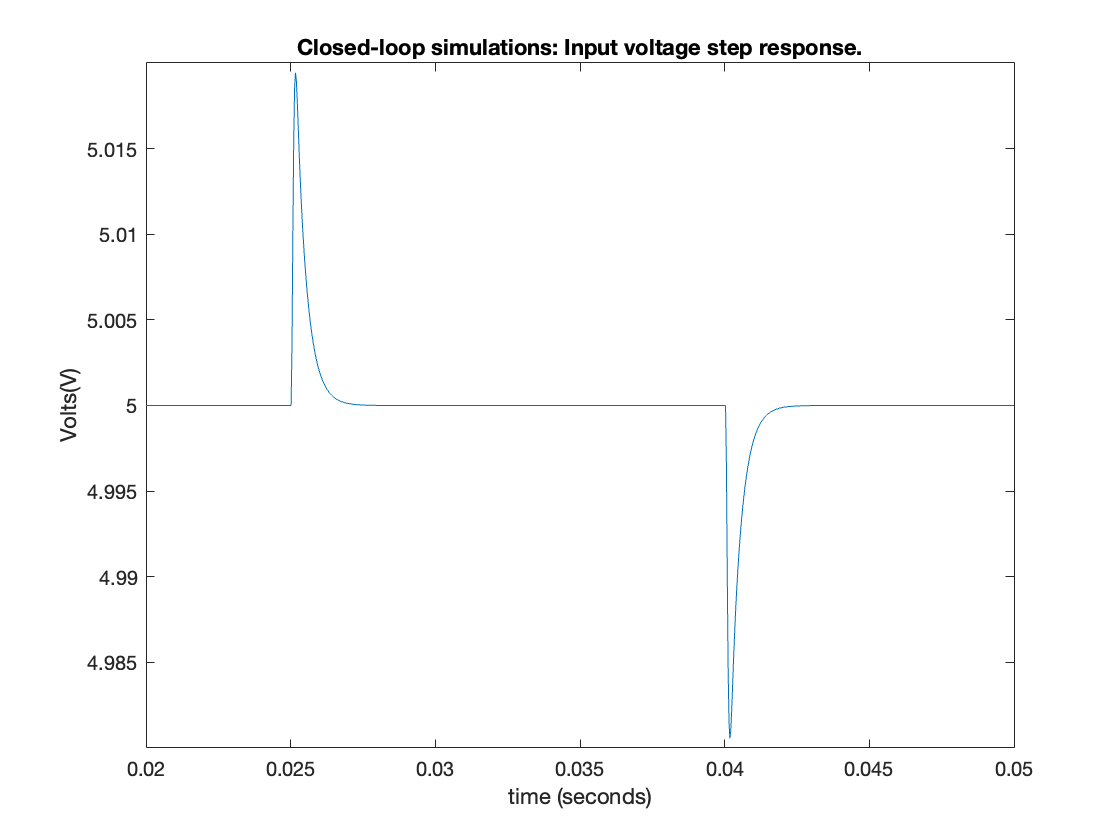

plot(t,y+V); 
title('Closed-loop simulations: Input voltage step response.');
ylabel('Volts(V)'); xlabel('time (seconds)');

% Task 3.a.iii
del_v = max(y) - min(y)

del_v = 0.0389

% Task 3.a.iv
SSE   = y(ind(end)) 

SSE = -2.2639e-17

 
% Task 3.b
% Group 2, Lab 6 
options = bodeoptions;
options.FreqUnits = 'Hz'; 
s = tf('s');
 q = 2*pi;
 
% Component values & Derived values
R  = 25;     Rb = 1000;    Ra = 1000;   
Vm = 10;     Vg = 10;      rL = 230e-3; 
L  = 560e-6; C  = 100e-6;  D  = 0.5;   
T0 = 0.5;     wI = q*17500; w1 = q*500;  
wz = q*1600; wp = q*16000; w0 = 673*q

w0 = 4.2286e+03

Q = (sqrt(L*C))/((rL*C)+(L/R));
T = (D*((wI*(1+(s/w1))*(1+(s/wz)))))/...
(s*(1+(s/wp))*(1+(s/(Q*w0))+((s/w0)^2)));
Gvg = D/(1+(s/(Q*w0))+((s/w0)^2));
Gvg_CL = Gvg/(1+T);

% Task 3.b.ii
V = D*Vg;
t = linspace(0.02, 0.05, 1000);
u = zeros(size(t));
ind = find(t>=0.025 & t<=0.04);
u(ind) = u(ind) + 1;
y = lsim (-Zout_CL, u, t); 

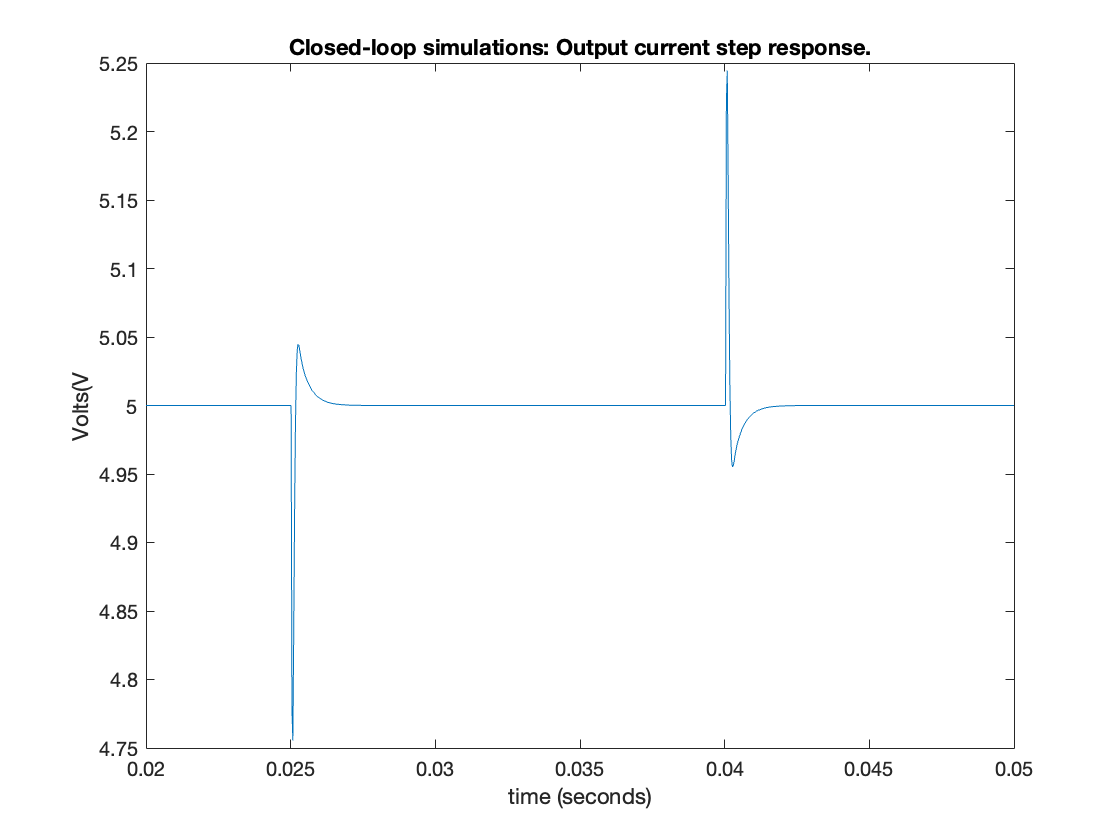

plot(t,y+V)
xlabel('time (seconds)')
title('Closed-loop simulations: Output current step response.');
ylabel('Volts(V')

fprintf('Zout_CL Values:\n')

Zout_CL Values:



% Task 3.b.iii
del_v = max(y) - min(y)

del_v = 0.4889


% Task 3.b.iv
SSE   = y(ind(end)) 

SSE = 1.8255e-17